# Problema 2 - Practic

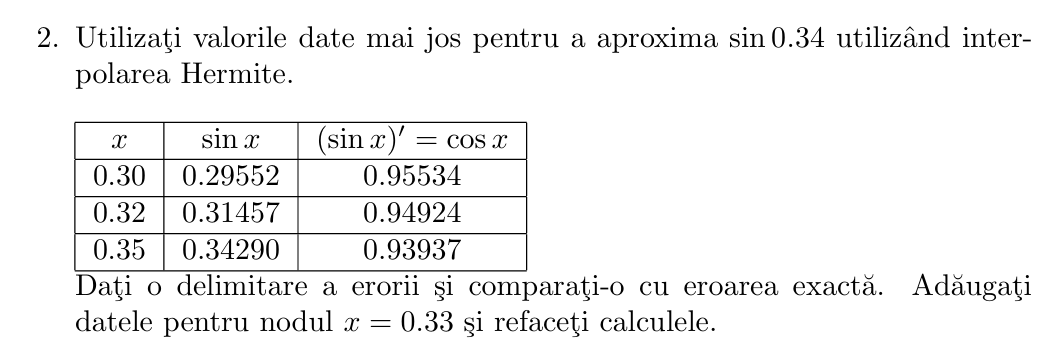

% PB1
function [p_val, coef, z] = interpolareHermite(x, f, df, x_eval)
% INTERPOLAREHERMITE - Interpolare Hermite cu noduri duble (forma Newton)
%
% INPUT:
%   x       - vector cu nodurile xi (lungime n)
%   f       - valorile functiei f(xi)
%   df      - valorile derivatei f'(xi)
%   x_eval  - punctele in care se evalueaza polinomul
%
% OUTPUT:
%   p_val   - valorile interpolate in punctele x_eval
%   coef    - coeficientii Newton ai polinomului Hermite
%   z       - vectorul de noduri extinse (cu dubluri)

    n = length(x);        % numarul de noduri initiale
    m = 2 * n;            % numarul de linii in tabela (fiecare nod apare de 2 ori)
    
    z = zeros(1, m);      % vectorul de noduri extinse: z_0, z_1, ..., z_{2n-1}
    Q = zeros(m, m);      % tabela Hermite de diferente divizate

    % P1, P2 
    for i = 1:n
        z(2*i - 1) = x(i);               
        z(2*i)     = x(i);              
        
        Q(2*i - 1, 1) = f(i);            
        Q(2*i,     1) = f(i);          
        
        Q(2*i,     2) = df(i);           

        % P3 - Daca nu suntem pe primul nod, calculam Q_{2i,1} 
        if i ~= 1
            Q(2*i - 1, 2) = (Q(2*i - 1, 1) - Q(2*i - 2, 1)) / ...
                           (z(2*i - 1) - z(2*i - 2));
        end
    end

    % P4 - Completam tabela Hermite (diferente divizate de ordin superior) 
    for i = 3:m
        for j = 3:i
            Q(i,j) = (Q(i,j-1) - Q(i-1,j-1)) / (z(i) - z(i-j+1));
        end
    end

    % P5 - Extragem coeficientii de pe diagonala
    coef = diag(Q);  % coeficientii din forma Newton

    % Evaluare polinom Hermite in punctele x_eval 
    p_val = zeros(size(x_eval));  % vector rezultat

    for k = 1:length(x_eval)
        val = coef(1);             % pornim cu primul coeficient
        produs = 1;

        for j = 2:m
            produs = produs * (x_eval(k) - z(j-1));
            val = val + coef(j) * produs;
        end

        p_val(k) = val;
    end
end

x = [0.30, 0.32, 0.35];
f = [0.29552, 0.31457, 0.34290];
df = [0.95534, 0.94924, 0.93937];

x_eval = 0.34;
[H_val1, coef1, z1] = interpolareHermite(x, f, df, x_eval);
real_val = sin(0.34);  % valoarea exactă

err1 = abs(H_val1 - real_val);

% Estimare derivata de ordin 6 pentru sin(x): tot sin(x), maxim = 1
prod_term = prod((x_eval - x).^2);
error_bound1 = (1 / factorial(6)) * prod_term;

% Calcul cu nodul suplimentar x=0.33
x2 = [0.30, 0.32, 0.33, 0.35];
f2 = [0.29552, 0.31457, sin(0.33), 0.34290];
df2 = [0.95534, 0.94924, cos(0.33), 0.93937];

[H_val2, coef2, z2] = interpolareHermite(x2, f2, df2, x_eval);
err2 = abs(H_val2 - real_val);

prod_term2 = prod((x_eval - x2).^2);
error_bound2 = (1 / factorial(8)) * prod_term2;  % gradul maxim e 7

Adaugarea x=0.33 reduce eroarea deoarece 0.33 este aproaoe de 0.34 iar functia sin este destul de neteda

fprintf("Valoarea exacta        sin(0.34) = %.8f\n", real_val);

Valoarea exacta        sin(0.34) = 0.33348709


fprintf("FARA x=0.33: Hermite   = %.8f, eroare = %.2e, estimare eroare = %.2e\n", H_val1, err1, error_bound1);

FARA x=0.33: Hermite   = 0.33348889, eroare = 1.80e-06, estimare eroare = 8.89e-14


fprintf("CU   x=0.33: Hermite   = %.8f, eroare = %.2e, estimare eroare = %.2e\n", H_val2, err2, error_bound2);

CU   x=0.33: Hermite   = 0.33349423, eroare = 7.14e-06, estimare eroare = 1.59e-19
